After a while of trying to choose a project, I decided to model baseball pitches using Simulink. I made a simulink block model that models a pitch based on the forces applied to it: gravity, drag, magnus effect. The block model itself is made from the assumption that all pitches are thrown at sea level. Additionally, I used research from NASA, and their values for the drag coefficient for a baseball. I also used a constant I found from a professor at the University of Texas that he used to calculate Magnus forces on a baseball. Both of these values are baseball specific, and both of the links will be included in my sources at the end. Another important assumption I made is that the spin rate and angle stay constant throughout its trajectory, which is not realistic. 

For the block model, I used a bunch of integrators to integrate forces applied to the baseball in the x, y, and z directions into velocities, and subsequently, positions. In the x direction, I included an initial velocity input, and incorporated a drag force acting in the negative x direction. For the y direction, I applied gravity in the negative y direction, and a magnus force that is determined by the inputs of spin rate and spin angle. Finally, in the z direction the only force is the magnus force, which again is determined by user inputs of spin rate/angle. 

I will be using baseball savant for all my statistical resources. The goal is to try to recreate the trajectories of different pitchers' most successful pitches, and understand why they are so successful by comparing them to their entire arsenal. I condensed my pitcher block model into a subsystem that takes in inputs: release velocity, spin angle, spin rate, release height -- all are created as Simulink Parameter objects that I can change values of directly from this live script. The outputs of the subsystem feed into my workspace, so i can call my plots and perform my analysis all in this live script. 

First, here's the outline of a strike zone I will be using for all the trajectories. This is just a universal strike zone I found online, and is really just here for show. Link to strike zone included at end. All my Simulink Parameter objects are initialized here. I also wrote some parameters by which my simulink simulations will run. For some reason I had trouble with step sizes when calling simulations from the live script, making these necessary. 

function [] = plotStrikeZone()
    x0 = 18.44;               
    y_low = 0.464566;         
    y_high = 1.119632;
    
    width = 0.4318;
    z_low = -width/2;
    z_high = width/2;
    
    X = [x0 x0 x0 x0];
    Y = [y_low y_high y_high y_low];
    Z = [z_low z_low z_high z_high];
    plot3(X, Z, Y); 
    patch(X, Z, Y, 'red', 'FaceAlpha', 0.15, 'EdgeColor', 'red');
end

initialVelocity = Simulink.Parameter(42.96);
spinRate = Simulink.Parameter(258);
spinAngle = Simulink.Parameter(pi/2);
releaseHeight = Simulink.Parameter(1.6154);

set_param("Baseball_Sim2", "MaxStep", "0.0001");
set_param("Baseball_Sim2", "RelTol",  "1e-5");
set_param("Baseball_Sim2", "AbsTol",  "1e-8");


The first pitcher I will be analyzing is Zack Wheeler, who is said to have the best fastball in MLB 2025. Wheeler on average releases his four-seam fastball at 96.1 mph, and acheives an average spin rate of 2470 rpm. Shown below is Zack Wheeler's four-seamer (blue) compared to the trajectory of a pitch without any spin in orange (only gravity acting on it). It's important to note that this is how pitch movement is usually defined. We can see that if Wheeler throws an ideal fastball, he would get 0.448 meters of lift on his fastball, or around 17 inches. 

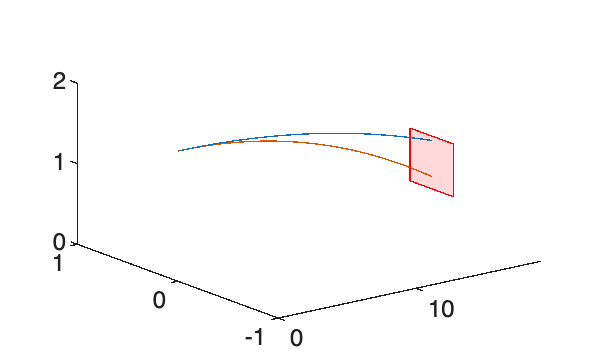

ZW_FBi = sim("Baseball_Sim2.slx");
spinRate.Value = 0;
ZW_FB = sim("Baseball_Sim2.slx");
plot3(ZW_FBi.x, ZW_FBi.z, ZW_FBi.y); 
hold on; plot3(ZW_FB.x, ZW_FB.z, ZW_FB.y); hold off
axis([0 19 -1 1 0 2]);
hold on; plotStrikeZone; hold off;


vert_rise = ZW_FBi.y(end) - ZW_FB.y(end)

vert_rise = 0.4477

However, he has an observed rise of 14.7 inches and 10.1 inches of tail. Since magnus force acts perpendicular to the velocity of the ball and spin axis, Wheeler's spin axis must be a bit over 90 degrees to constitute for the lateral armside movement. Let's see if we can figure out his spin axis using my model. 

spinRate.Value = 258;
spinAngle.Value = pi/2;
theta = pi/2;
step = 0.5;

for i = 2000
    theta = theta + step;
    spinAngle.Value = theta;
    ZW_FBr = sim("Baseball_Sim2.slx");
    v_break = ZW_FBr.y(end) - ZW_FB.y(end);
    h_break = ZW_FBr.z(end) - ZW_FB.z(end);
    if abs(-h_break - 0.25654) <= 0.05
        break
    end
end

[h_break,v_break]

ans =    -0.2146    0.3929


theta

theta = 2.0708

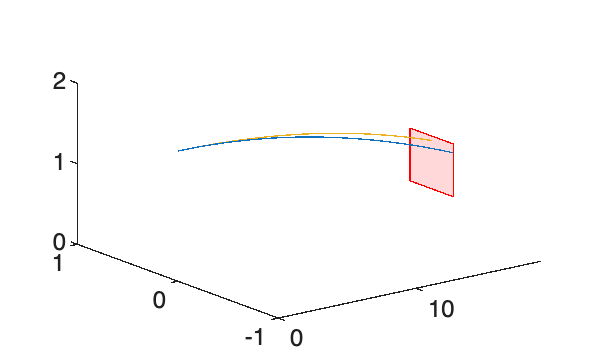


plot3(ZW_FBr.x, ZW_FBr.z, ZW_FBr.y); axis([0 19 -1 1 0 2]);
hold on; plotStrikeZone;
plot3(ZW_FBi.x, ZW_FBi.z, ZW_FBi.y);
hold off;

I knew that the spin angle would be just above 90 degrees, so I set a step length of 0.5 radians, stopping the loop once the horizontal break reaches within 2 inches of the desired amount of 10.1 inches. We are left with a spin axis of 2.07 radians, or 118.65 degrees, armside break of 8.45 inches, and vertical rise of 15.47 inches. Not exactly his values but pretty close considering our idealized (kind of) system -- both movement values are within 2 inches. Here are all three of the pitches analyzed above plotted together. We can see they all cross homeplate at the same time: 0.4515 seconds after released by pitcher. 

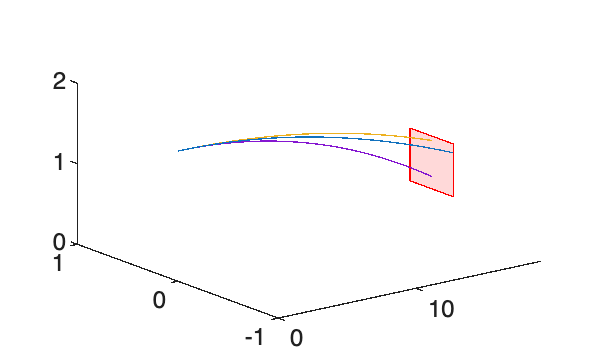

plot3(ZW_FBr.x, ZW_FBr.z, ZW_FBr.y); axis([0 19 -1 1 0 2]);
hold on; plotStrikeZone;
plot3(ZW_FBi.x, ZW_FBi.z, ZW_FBi.y);
plot3(ZW_FB.x, ZW_FB.z, ZW_FB.y);
hold off;


[ZW_FB.time(end)
ZW_FBi.time(end)
ZW_FBr.time(end)]

ans =     0.4515
    0.4515
    0.4515


Now moving on to the second pitcher. I told a friend about this project and he asked me to analyze a specific pitch: Logan Gilbert's splitter. The splitter, or split finger fastball, is an offspeed pitch, designed to look like a fastball, but drop sharply as it reaches home plate due to its low spin rate. The splitter is one of the more increasingly used pitch in the MLB. For reference, in the 2023 MLB season there were 4000 more splitters thrown than any other year in the pitch tracking era. It felt like every other pitcher in the postseason this year had a nasty splitter, from the rookie Trey Yesavage on the Blue Jays to the subject of our analysis today, Logan Gilbert. 

To see why Gilbert's splitter is so devastating to hitters, we first need to recreate his fastball. On average, he releases his four-seam fastball 5.8 feet off the ground, at 95.4 mph, and with a spin rate of 2115 rpm. Let's log all these parameters and a spin angle of 90 degrees, and try to recreate his fastball.

clear;

set_param("Baseball_Sim2", "MaxStep", "0.0001");
set_param("Baseball_Sim2", "RelTol",  "1e-5");
set_param("Baseball_Sim2", "AbsTol",  "1e-8");

initialVelocity = Simulink.Parameter(42.64762);
spinRate = Simulink.Parameter(0);
spinAngle = Simulink.Parameter(pi/2);
releaseHeight = Simulink.Parameter(1.76784);


LG_FB = sim("Baseball_Sim2.slx");

spinRate.Value = 2115*0.1047;

LG_FBr = sim("Baseball_Sim2.slx");
v_break = LG_FBr.y(end) - LG_FB.y(end)

v_break = 0.3870

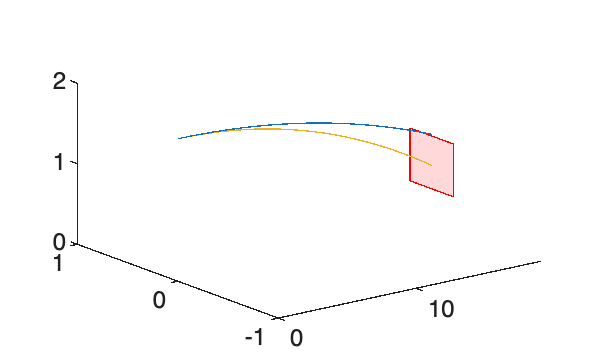


plot3(LG_FBr.x, LG_FBr.z, LG_FBr.y); axis([0 19 -1 1 0 2]);
hold on;
plotStrikeZone; plot3(LG_FB.x, LG_FB.z, LG_FB.y);
hold off;

We can see that even when we give Gilbert an ideal fastball spin axis of 90 degrees, we still can't acheive the 16.5 inches of induced rise he acheives. I did some research on this, and it might be due to his exceptional release point. Gilbert releases his pitch 5.8 feet high, but also about two feet in front of the mound. I created a new simulink model, same as my old one, but also taking in a parameter releasePointX. Let's log Gilbert's release point and see if we can induce any more lift. 

releasePointX = Simulink.Parameter(0.6096);
set_param("Baseball_Sim3", "MaxStep", "0.0001");
set_param("Baseball_Sim3", "RelTol",  "1e-5");
set_param("Baseball_Sim3", "AbsTol",  "1e-8");

LG_FBi = sim("Baseball_Sim3.slx");
v_break = LG_FBi.y(end) - LG_FB.y(end)

v_break = 0.4301

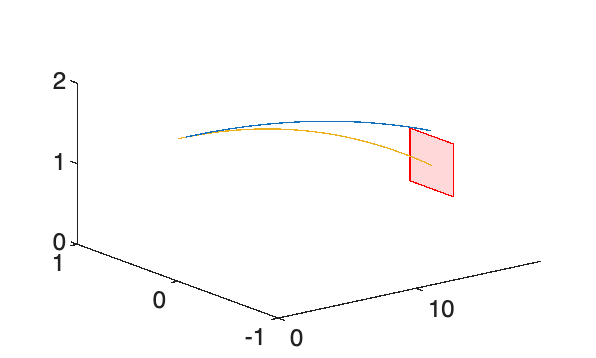



plot3(LG_FBi.x, LG_FBi.z, LG_FBi.y); axis([0 19 -1 1 0 2]);
hold on;
plotStrikeZone; plot3(LG_FB.x, LG_FB.z, LG_FB.y);
hold off;

We can see that the updated release point of Gilbert's fast ball give us almost two more inches of induced lift. This is likely the reason Gilbert get's so much rise on his fastball in spite of having a lower spin rate than Zack Wheeler. Let's try to tweak his spin angle to somewhat reach the amount of tail on his fastball, then move on to the splitter. 

spinAngle.Value = 2.0;

LG_FBr = sim("Baseball_Sim3.slx");

h_break = abs(LG_FBr.z(end) - LG_FB.z(end))* 39.37

h_break = 5.9157


v_break = abs(LG_FBr.y(end) - LG_FB.y(end))*39.37

v_break = 15.6456

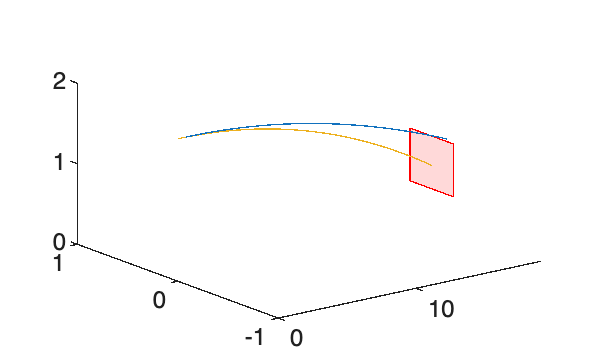


plot3(LG_FBr.x, LG_FBr.z, LG_FBr.y); axis([0 19 -1 1 0 2]);
hold on;
plotStrikeZone; plot3(LG_FB.x, LG_FB.z, LG_FB.y);
hold off;

I have calibrated Glibert's fastball to have a spin angle of 2 radians, or 114 degrees. I chose this angle to try and preserve his unusual vertical movement since it is a critical piece of his arsenal.

Gilbert releases his splitter 5.7 feet off the ground and about a foot in front of the plate, with a spin rate of 727 rpm, and velocity of 81.7 mph. He acheives one inch of drop and 4.8 inches of tail. Let's set parameter to create the spinless version of the pitch, then tweak it to reach desired movement.

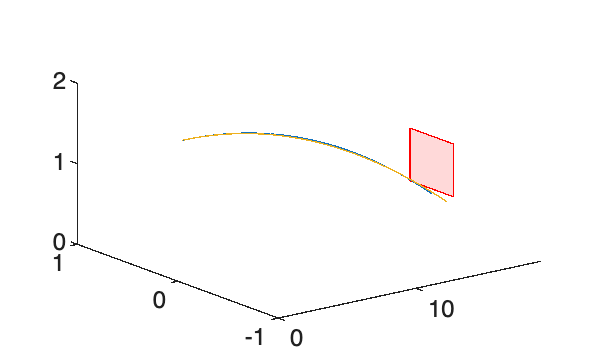

spinRate.Value = 0;
initialVelocity.Value = 36.52317;
releaseHeight.Value = 1.73736;
releasePointX.Value = 0.3048;
spinAngle.Value = 0;
LG_SP = sim("Baseball_Sim3.slx");

spinRate.Value = 727 * 0.1047;
spinAngle.Value = pi + 0.2;

LG_SPr = sim("Baseball_Sim3.slx");

plot3(LG_SP.x,LG_SP.z,LG_SP.y); axis([0 19 -1 1 0 2]);
hold on;
plotStrikeZone;
plot3(LG_SPr.x, LG_SPr.z, LG_SPr.y);
hold off;


yBreak = (LG_SPr.y(end) - LG_SP.y(end))*39.37

yBreak = -1.1739

hBreak = (LG_SPr.z(end) - LG_SP.z(end))*39.37

hBreak = -5.7912

With a spin axis of just over pi, we are able to recreate Gilbert's splitter pretty well, acheiving a bit over an inch of drop and almost 6 inches of armside movement. By overlaying his fastball and his splitter we can see just how deceptive this pitch is. We can see that coming out of the hand these two pitches are designed to look the same. However, his fast ball ends up 30 inches higher than his splitter, and crosses home plate almost a tenth of a second earlier. This is why he is reaching a whopping 50% whiff rate on his split finger fastball. 

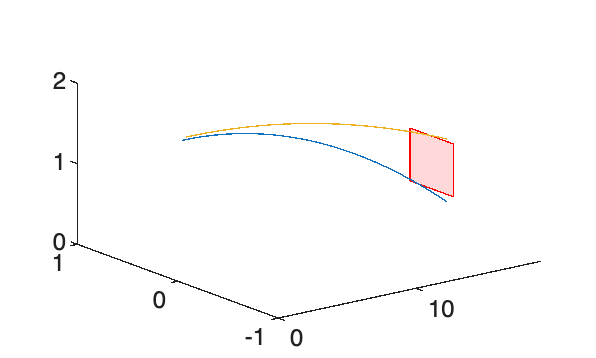

plot3(LG_SPr.x, LG_SPr.z, LG_SPr.y); axis([0 19 -1 1 0 2]);
hold on; 
plotStrikeZone;
plot3(LG_FBr.x, LG_FBr.z, LG_FBr.y);
hold off;


v_diff = (LG_FBr.y(end) - LG_SPr.y(end))*39.37

v_diff = 30.6502

[LG_FBr.time(end) , LG_SPr.time(end)]

ans =     0.4390    0.5218


Finally, Gilbert's arsenal is not complete without his curveball, a breaking pitch that tunnels nicely with his fastball and splitter. He releases his curveball 5.7 feet off the ground and a foot in front of the plate, with a spin rate of 2183 rpm, and velocity of 82.1 mph. He acheives 3.1 inches of drop, and 12.9 inches of armside break. 

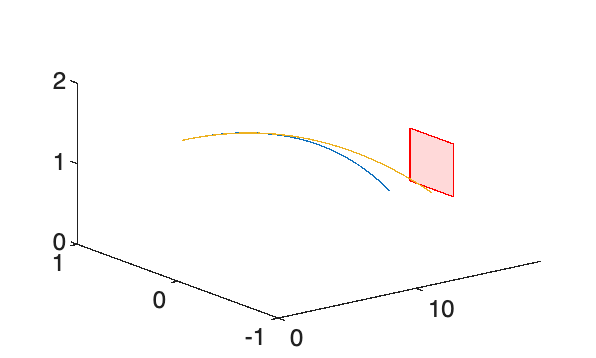

spinRate.Value = 0;
spinAngle.Value = -0.4;
initialVelocity.Value = 36.70198;

LG_CB = sim("Baseball_Sim3.slx");

spinRate.Value = 2183 * 0.1047;
LG_CBr = sim("Baseball_Sim3.slx");

plot3(LG_CBr.x, LG_CBr.z, LG_CBr.y); axis([0 19 -1 1 0 2]);
hold on; 
plotStrikeZone;
plot3(LG_CB.x, LG_CB.z, LG_CB.y);
hold off;


y_break = (LG_CBr.y(end) - LG_CB.y(end))*39.37

y_break = -6.8759

h_break = (LG_CBr.z(end) - LG_CB.z(end))*39.37

h_break = 16.2629

With a spin angle of -0.4 radians (-23 degrees) we are able to acheive a horizontal break of 16.26 inches and vertical break of 6.88 inches. Although this is more extreme than his average, there are pitches within his 100 pitch sample on baseball savant where he does increase break. 

Below are Gilbert's three pitches (splitter, curveball, four-seam fastball) plotted together. I defined "movement" in the code lines below comparing the splitter and curveball movement to the fastball. We can see the curveball gets even more vertical drop than the splitter due to the spin rate and axis. The fastball, splitter, and curveball pass home plate at 0.439, 0.522, and 0.519 seconds after released by the pitcher, respectively. 

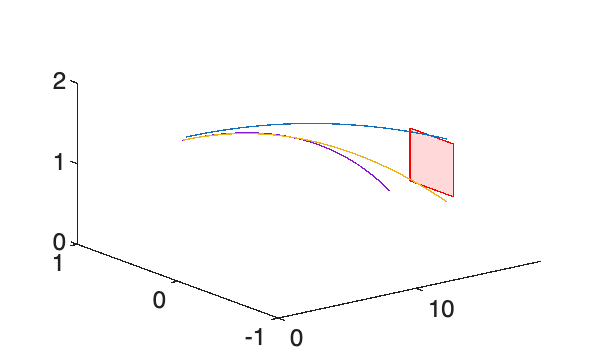

plot3(LG_FBr.x,LG_FBr.z,LG_FBr.y); axis([0 19 -1 1 0 2]);
hold on;
plotStrikeZone;
plot3(LG_SPr.x,LG_SPr.z,LG_SPr.y);
plot3(LG_CBr.x,LG_CBr.z,LG_CBr.y); 
hold off;


Curveball_Movement = [(LG_CBr.z(end)-LG_FBr.z(end))*39.37,(LG_CBr.y(end)-LG_FBr.y(end))*39.37]

Curveball_Movement =    22.1786  -35.8416


Splitter_Movement = [(LG_SPr.z(end)-LG_FBr.z(end))*39.37,(LG_SPr.y(end)-LG_FBr.y(end))*39.37]

Splitter_Movement =     0.1245  -30.6502



fb_time = LG_FBr.time(end)

fb_time = 0.4390

sp_time = LG_SPr.time(end)

sp_time = 0.5218

cb_time = LG_CBr.time(end)

cb_time = 0.5193

Finally, my last pitcher will be Caleb Thielbar of the Chicago Cubs, a personal choice. He has three main pitches: four-seam, curveball, sweeper. I will try to recreate his arsenal below.

initialVelocity.Value = 41.48531;
releaseHeight.Value = 1.88976;
releasePointX.Value = 0;
spinRate.Value = 0;
spinAngle.Value = pi/2 - 0.15;

CT_FB = sim("Baseball_Sim3.slx");
spinRate.Value = 2327*0.1047;
CT_FBr = sim("Baseball_Sim3.slx");

h_break = (CT_FBr.z(end) - CT_FB.z(end))*39.37

h_break = 2.5755

v_break = (CT_FBr.y(end) - CT_FB.y(end))*39.37

v_break = 17.0414


initialVelocity.Value = 33.975;
spinRate.Value = 0;
spinAngle.Value = -pi/2 - 0.3;

CT_CB = sim("Baseball_Sim3.slx");
spinRate.Value = 2607*0.1047;
CT_CBr = sim("Baseball_Sim3.slx");

h_break = (CT_CBr.z(end) - CT_CB.z(end))*39.37

h_break = -6.9675

v_break = (CT_CBr.y(end) - CT_CB.y(end))*39.37

v_break = -22.5239


initialVelocity.Value = 36.16554;
releaseHeight.Value = 1.85928;
spinRate.Value = 0;
spinAngle.Value = pi;

CT_SW = sim("Baseball_Sim3.slx");
spinRate.Value = 2578*0.1047;
CT_SWr = sim("Baseball_Sim3.slx");

h_break = (CT_SWr.z(end) - CT_SW.z(end))*39.37

h_break = -21.9025

v_break = (CT_SWr.y(end) - CT_SW.y(end))*39.37

v_break = 0

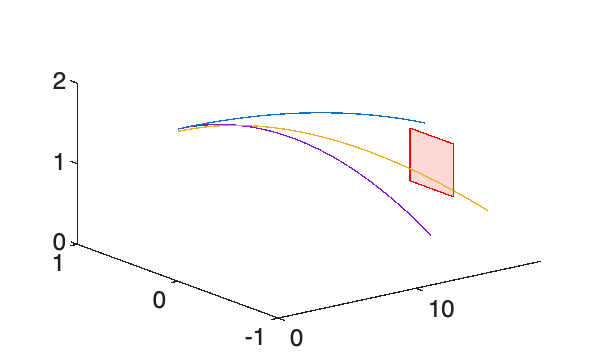



plot3(CT_FBr.x,CT_FBr.z,CT_FBr.y); axis([0 19 -1 1 0 2]);
hold on;
plotStrikeZone;
plot3(CT_SWr.x,CT_SWr.z,CT_SWr.y);
plot3(CT_CBr.x,CT_CBr.z,CT_CBr.y); 
hold off;


Curveball_Movement = [(CT_CBr.z(end)-CT_FBr.z(end))*39.37,(CT_CBr.y(end)-CT_FBr.y(end))*39.37]

Curveball_Movement =    -9.5430  -60.2673


Sweeper_Movement = [(CT_SWr.z(end)-CT_FBr.z(end))*39.37,(CT_SWr.y(end)-CT_FBr.y(end))*39.37]

Sweeper_Movement =   -24.4781  -31.5583



fb_time = CT_FBr.time(end)

fb_time = 0.4675

sp_time = CT_SWr.time(end)

sp_time = 0.5363

cb_time = CT_CBr.time(end)

cb_time = 0.5709

I kept the commentary short throught that process but I'm doing the same as I have done for the last couple of pitchers. Thielbar's movement and break numbers are a bit exaexaggerated due to our assumption of spin rate/angle not changing, and he does acheive unusually high spin on his pitches. Although higher than observed we can agree that 60 inch vertical movement between a curveball and fastball is ridiculous. 

Overall, using MATLAB/Simulink to model different pitches and recreate a pitcher's arsenal was super interesting. It also goes to show how much execution matters for pitchers. Small tweaks in spin angle and rate can completely change the trajectory of your pitch. When it comes to hitting, this project has shown me just how difficult it is to put barrel on the ball when in the batter's box. All the pitches I modeled took under six tenths of a second to reach home plate, and had a huge amount of induced movement. 

Sources:

[https://www.baseballprospectus.com/news/article/40891/prospectus-feature-the-universal-strike-zone/](https://www.baseballprospectus.com/news/article/40891/prospectus-feature-the-universal-strike-zone/)

[https://baseball.physics.illinois.edu/aero.html](https://baseball.physics.illinois.edu/aero.html)

[https://farside.ph.utexas.edu/teaching/329/lectures/node44.html](https://farside.ph.utexas.edu/teaching/329/lectures/node44.html)

[https://www1.grc.nasa.gov/beginners-guide-to-aeronautics/drag-on-a-baseball/](https://www1.grc.nasa.gov/beginners-guide-to-aeronautics/drag-on-a-baseball/)

Logan Gilbert release points:

[https://blogs.fangraphs.com/logan-gilbert-secret-weapon-changeup/](https://blogs.fangraphs.com/logan-gilbert-secret-weapon-changeup/)

[https://www.brooksbaseball.net/velo.php?player=669302&b_hand=-1&gFilt=&pFilt=FA|SI|FC|CU|SL|CS|KN|CH|FS|SB&time=month&minmax=ci&var=x0&s_type=2&startDate=03/30/2007&endDate=12/07/2025](https://www.brooksbaseball.net/velo.php?player=669302&b_hand=-1&gFilt=&pFilt=FA|SI|FC|CU|SL|CS|KN|CH|FS|SB&time=month&minmax=ci&var=x0&s_type=2&startDate=03/30/2007&endDate=12/07/2025)

[https://baseballsavant.mlb.com/player-scroll?player_id=669302#rp_CUKC](https://baseballsavant.mlb.com/player-scroll?player_id=669302#rp_CUKC)

Baseball Savant Profiles:

Wheeler: [https://baseballsavant.mlb.com/savant-player/zack-wheeler-554430?stats=statcast-r-pitching-mlb](https://baseballsavant.mlb.com/savant-player/zack-wheeler-554430?stats=statcast-r-pitching-mlb)

Gilbert: [https://baseballsavant.mlb.com/savant-player/logan-gilbert-669302?stats=statcast-r-pitching-mlb](https://baseballsavant.mlb.com/savant-player/logan-gilbert-669302?stats=statcast-r-pitching-mlb)

Thielbar: [https://baseballsavant.mlb.com/savant-player/caleb-thielbar-573204?stats=statcast-r-pitching-mlb](https://baseballsavant.mlb.com/savant-player/caleb-thielbar-573204?stats=statcast-r-pitching-mlb)